% 准备数据
t = 0 : pi/50 : 10*pi

t =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


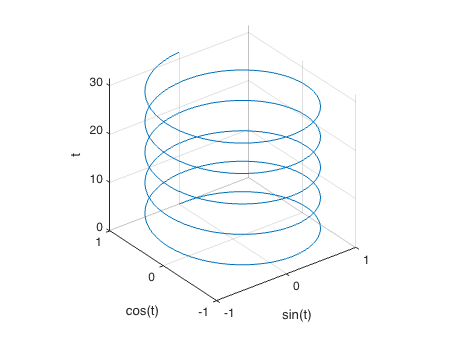


% 绘制图像
plot3(sin(t), cos(t), t)

% 添加轴说明
xlabel('sin(t)')
ylabel('cos(t)')
zlabel('t')

grid on

axis square

# 三维图和子图

## 1. 三维曲面图

surf 函数可以用来做三维曲面图。一般是展示 z=z(x, y) 的图像

首先需要用 mesharid 创建好空间上 (x, y) 点

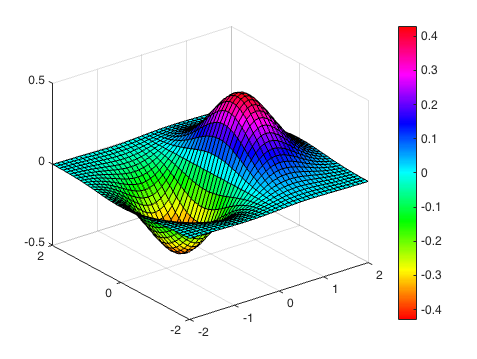

[X, Y] = meshgrid(-2 : 0.1 : 2);
Z = X .* exp(-X .^ 2 - Y .^2);
surf(X, Y, Z);

% 设置颜色
colormap hsv % hsv winter summer 一般用 hsv，这也是默认的

% 色条显示
colorbar